clear
set(groot,'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex');  
set(groot, 'defaultLegendInterpreter','latex');

fileDirectory = fullfile('D:\Proton Drive\Lasseb200\My files\Master\MachineLearning\TestData\EsbenData_All');
%fileDirectory = fullfile('C:\Users\Lasse\Proton Drive\Lasseb200\My files\Master\MachineLearning\TestData\EsbenData_All');
load(fullfile(fileDirectory,'DecemberData4.mat'))

amplitude = zscore(amplitude);
phase = zscore(phase);
delay = zscore(groupDelay);
%delay = delay ./ vecnorm(delay,2,2);

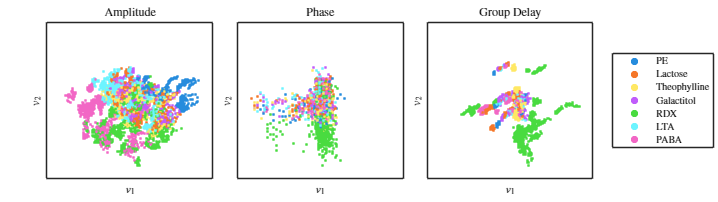

% --- Data Preparation ---
datasets = {amplitude, phase, delay};
titles = {'Amplitude', 'Phase', 'Group Delay'};
[groupNames, ~, groupIndices] = unique(chemicals, 'stable');
numGroups = numel(groupNames);
cmap = orderedcolors("glow12"); 

% --- Layout Setup ---
figure('Units', 'normalized', 'Position', [0.1, 0.4, 0.8, 0.4]); 
t = tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');

% Loop through the 3 datasets
for i = 1:3
    ax = nexttile;
    hold on;
    
    % LDA Projection
    currentData = datasets{i};
    idx_training = cv.training(1);
    %v = LDA(currentData(idx_training, :), chemicals(idx_training));
    v = PCA(currentData);
    % Use only first 2 columns for the 2D plot
    Projected = currentData * v(:, 1:2); 
    
    % Smart Limits: 1.2x the max of what is actually being plotted
    limitX = max(abs(Projected(:,1))) * 1.2;
    limitY = max(abs(Projected(:,2))) * 1.2;
    
    % Shuffle for plotting
    n = size(Projected, 1);
    sIdx = randperm(n);
    
    % Plot the data (Hidden from legend)
    scatter(Projected(sIdx, 1), Projected(sIdx, 2), 5, ...
        cmap(groupIndices(sIdx), :), 'filled', 'HandleVisibility', 'off');
    
    % Formatting
    xlim([-limitX, limitX]);
    ylim([-limitY, limitY]);
    title(titles{i});
    xlabel('$v_1$'); ylabel('$v_2$');
    xticks([]); yticks([]);
    set(gca, 'Box', 'on', 'Layer', 'top');
end

% --- Single Shared Legend ---
% We create the proxy objects on the LAST axes used, but they are invisible (NaN)
h = zeros(1, numGroups);
for j = 1:numGroups
    h(j) = plot(NaN, NaN, 'o', 'MarkerFaceColor', cmap(j,:), ...
         'MarkerEdgeColor', 'none', 'MarkerSize', 6, ...
         'DisplayName', char(groupNames(j)));
end

% Move the legend to the right of the entire layout
lgd = legend(h, 'Location', 'eastoutside');
lgd.Layout.Tile = 'east';

%printPDF('LDAs2',0.9,7,5,1,'none')
